clc;
clear;
close all;


% % Read in Data
Titanic_table = readtable('train.csv');
Titanic_train_data = (table2cell(Titanic_table));

class = cell2mat(Titanic_train_data(:,3));
survived = cell2mat(Titanic_train_data(:,2));
sex = Titanic_train_data(:,5);
age = cell2mat(Titanic_train_data(:,6));
sibsp = cell2mat(Titanic_train_data(:,7));
parch = cell2mat(Titanic_train_data(:,8));
fare = cell2mat(Titanic_train_data(:,10));


% Replace NaN values in age by mean age
mean_age = mean(age,'omitnan');
age(isnan(age))= mean_age;

% Discretize age to bins
% Increase categories for better accuracy
Age_Categorized = discretize(age, [0 10 20 30 50 100],'categorical',{'Under 10', '10-20', '20-30', '30-50', 'Above 50'});

% number of Family mebers on board
family = sibsp + parch;

Age_Categorized = grp2idx(Age_Categorized);
sex = grp2idx(sex);
tbl = table(class, sex, Age_Categorized, family, fare, survived);


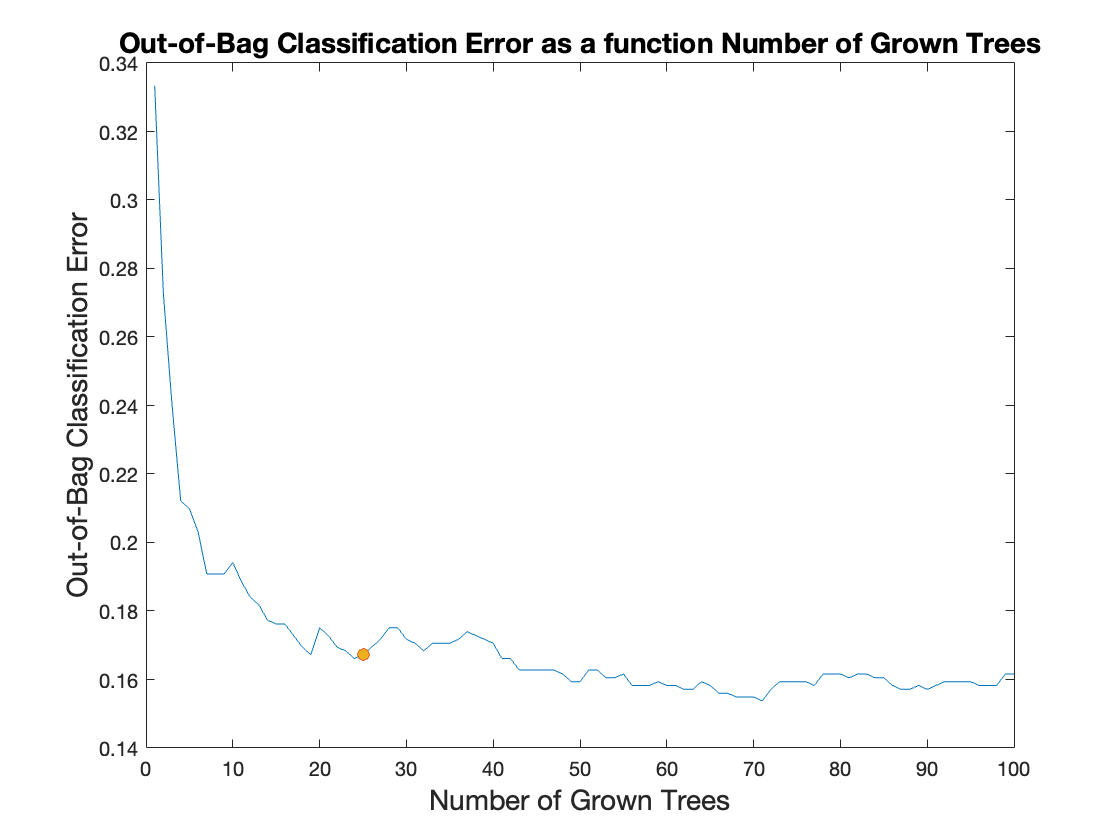

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fit Random Forest
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

b = TreeBagger(100,tbl(:,1:5),tbl(:,6),'OOBPredictorImportance','On');
optimal_forest_size = 25;

figure('Name', 'Question5-Random Forest')
oob = oobError(b);
plot(oob); hold on; 
plot(optimal_forest_size,oob(optimal_forest_size), 'o', 'MarkerFaceColor',[0.9290 0.6940 0.1250])
xlabel('Number of Grown Trees', 'FontSize',14)
ylabel('Out-of-Bag Classification Error', 'FontSize',14)
title('Out-of-Bag Classification Error as a function Number of Grown Trees', 'FontSize',14)

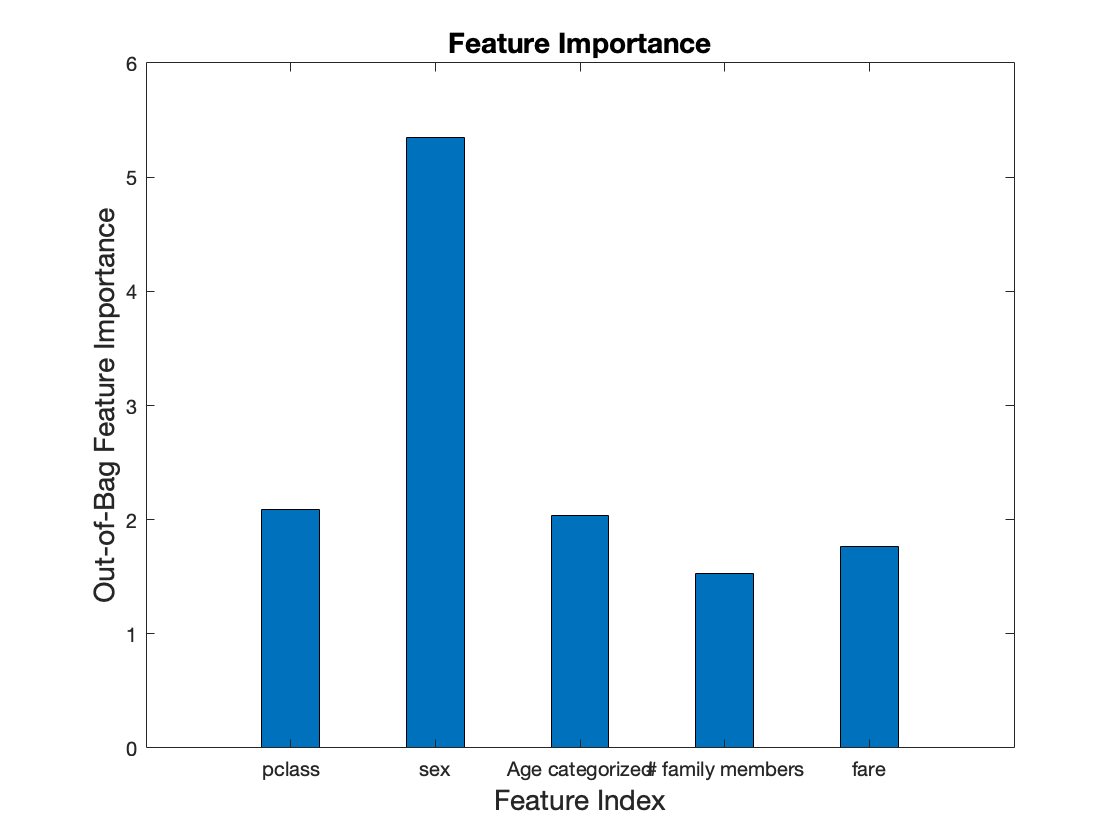


% Estimate feature importance.
figure('Name', 'Question5-Random Forest Feature Importance')
bar(b.OOBPermutedPredictorDeltaError,0.4)
xlabel('Feature Index', 'FontSize',14)
ylabel('Out-of-Bag Feature Importance', 'FontSize',14)
title('Feature Importance', 'FontSize',14)
labels = {'pclass','sex', 'Age categorized', '# family members','fare'};
xticklabels(labels)



b_optimal = TreeBagger(28,tbl(:,1:5),tbl(:,6),'OOBPredictorImportance','off','OOBPrediction','on');

% Predict
[Yfit,Sfit] = oobPredict(b_optimal);

Confusion_Matrix_RandomForest = confusionmat(survived,str2double(Yfit));
Accuracy_RandomForest = trace(Confusion_Matrix_RandomForest)/sum(Confusion_Matrix_RandomForest, 'all')

Accuracy_RandomForest = 0.8294

%% Prediction on Test Set  

% Read in test Data
Titanic_table_test = readtable('test.csv');
Titanic_data_test = (table2cell(Titanic_table_test));

PassengerId = cell2mat(Titanic_data_test(:,1)); 
class = cell2mat(Titanic_data_test(:,2));
sex = Titanic_data_test(:,4);
age_test = cell2mat(Titanic_data_test(:,5));
sibsp_test = cell2mat(Titanic_data_test(:,6));
parch_test = cell2mat(Titanic_data_test(:,7));
fare = cell2mat(Titanic_data_test(:,9));

% Replace NaN values in age by mean age
mean_age_test = mean(age_test,'omitnan');
age_test(isnan(age_test))= mean_age_test;

% Discretize age to bins
Age_Categorized = discretize(age_test, [0 10 20 30 50 100],'categorical',{'Under 10', '10-20', '20-30', '30-50', 'Above 50'});

% number of Family mebers on board
family = sibsp_test + parch_test;

Age_Categorized = grp2idx(Age_Categorized);
sex = grp2idx(sex);
tbl_test = table(class, sex, Age_Categorized, family, fare);

% % % Using RF
 ypred_RF = predict(b_optimal,tbl_test);
 generate_csv(PassengerId, str2double(ypred_RF))


function generate_csv(PassengerId, predicted_labels)

% to round the probabilities to 0 and 1 i.e.0:not survived, 1:survived
Survived = round(predicted_labels);

out = table(PassengerId, Survived);
writetable(out,'predictions_till.csv')

end


% Find Resubstitution loss and Cross validation loss for any model
function [resubstitution_loss, cv_loss] = loss_metrics(model)
% Misclassification error
resubstitution_loss = resubLoss(model);
% cross-validation evaluation
cvc_model = crossval(model);
cv_loss = kfoldLoss(cvc_model);
end